clear all; close all; clc;

%% 1. 系统参数设置
% 11位巴克码 (Barker Code) 作为SFD (帧起始定界符)
barker_code = [1 1 1 -1 -1 -1 1 -1 -1 1 -1];
barker_bits = (barker_code + 1) / 2; % 转换为0/1格式
% 前同步码 
preamble = repmat([1 0], 1, 8); % 16位交替的1010...模式
% 信道参数
SNR_dB = 10; % 信噪比 (dB)
noise_variance = 10^(-SNR_dB/10);
%% 2. 发送端 (TX) - 数据编码和打包
% 原始文本数据
message_text = 'hello world';
fprintf('原始消息: "%s"\n', message_text);

原始消息: "hello world"



% 转换为字节 (ASCII编码)
message_bytes = uint8(message_text);
data_length = length(message_bytes);
fprintf('数据长度: %d 字节\n', data_length);

数据长度: 11 字节



% 计算校验和 (简单异或校验)
checksum = uint8(0);
for i = 1:data_length
    checksum = bitxor(checksum, message_bytes(i));
end
fprintf('计算得到的校验和: 0x%02X\n', checksum);

计算得到的校验和: 0x20



% 将字节转换为比特流
header_bits = dec2bin_custom(data_length, 8); % 8位长度字段
payload_bits = [];
for i = 1:data_length
    payload_bits = [payload_bits, dec2bin_custom(message_bytes(i), 8)];
end
checksum_bits = dec2bin_custom(checksum, 8); % 8位校验和

% 构建完整的PPDU (Physical Protocol Data Unit)
ppdu_bits = [preamble, barker_bits, header_bits, payload_bits, checksum_bits];
total_bits = length(ppdu_bits);
fprintf('PPDU总长度: %d 比特\n', total_bits);

PPDU总长度: 131 比特


fprintf('- 前同步码: %d 比特\n', length(preamble));

- 前同步码: 16 比特


fprintf('- SFD (巴克码): %d 比特\n', length(barker_bits));

- SFD (巴克码): 11 比特


fprintf('- 帧头: %d 比特\n', length(header_bits));

- 帧头: 8 比特


fprintf('- 净荷: %d 比特\n', length(payload_bits));

- 净荷: 88 比特


fprintf('- 校验和: %d 比特\n', length(checksum_bits));

- 校验和: 8 比特



%% 3. 信道传输 (BPSK调制 + AWGN噪声)
fprintf('\n--- 信道传输 ---\n');


--- 信道传输 ---



% BPSK调制: 0->-1, 1->+1
modulated_signal = double(2*ppdu_bits - 1); % 确保为双精度类型

% 添加AWGN噪声
noise = sqrt(noise_variance/2) * (randn(size(modulated_signal)) + 1j*randn(size(modulated_signal)));%模拟高斯白噪声
received_signal = modulated_signal + real(noise); % 只取实部（BPSK）

fprintf('信噪比: %.1f dB\n', SNR_dB);

信噪比: 10.0 dB


fprintf('噪声方差: %.4f\n', noise_variance);

噪声方差: 0.1000



%% 4. 接收端 (RX) - 解调和初步处理
fprintf('\n--- 接收端处理 ---\n');


--- 接收端处理 ---



% BPSK解调 (硬判决)
received_bits = received_signal > 0;

% 计算误码率 (仅用于分析)
bit_errors = sum(ppdu_bits ~= received_bits);
BER = bit_errors / total_bits;
fprintf('传输误码数: %d / %d\n', bit_errors, total_bits);

传输误码数: 0 / 131


fprintf('误码率 (BER): %.6f\n', BER);

误码率 (BER): 0.000000



%% 5. 帧同步 - 使用滑动自相关器搜索巴克码
fprintf('\n--- 帧同步处理 ---\n');


--- 帧同步处理 ---



% 将巴克码转换为BPSK格式用于相关运算
barker_template = 2*barker_bits - 1;
barker_length = length(barker_template);

% 滑动自相关
correlation_output = [];
search_length = length(received_signal);

for i = 1:(search_length - barker_length + 1)
    % 提取当前窗口的信号段
    signal_segment = received_signal(i:i+barker_length-1);
    
    % 计算归一化互相关
    correlation = sum(signal_segment .* barker_template) / barker_length;
    correlation_output = [correlation_output, correlation];
end

% 寻找相关峰值
[max_correlation, peak_position] = max(correlation_output);
detected_sfd_position = peak_position;

fprintf('最大相关值: %.4f\n', max_correlation);

最大相关值: 1.0780


fprintf('检测到的SFD位置: %d\n', detected_sfd_position);

检测到的SFD位置: 17


fprintf('实际SFD位置: %d\n', length(preamble) + 1);

实际SFD位置: 17


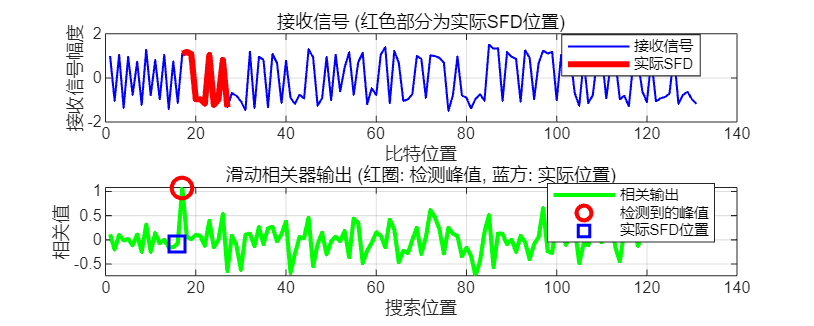


% 可视化相关器输出
figure('Name', '巴克码同步 - 相关器输出', 'Position', [100, 100, 1000, 400]);

subplot(2,1,1);
plot(1:length(received_signal), received_signal, 'b-', 'LineWidth', 1);
hold on;
% 标记实际的SFD位置
actual_sfd_start = length(preamble) + 1;
actual_sfd_end = actual_sfd_start + barker_length - 1;
plot(actual_sfd_start:actual_sfd_end, received_signal(actual_sfd_start:actual_sfd_end), 'r-', 'LineWidth', 3);
xlabel('比特位置');
ylabel('接收信号幅度');
title('接收信号 (红色部分为实际SFD位置)');
grid on;
legend('接收信号', '实际SFD', 'Location', 'best');

subplot(2,1,2);
plot(1:length(correlation_output), correlation_output, 'g-', 'LineWidth', 2);
hold on;
plot(detected_sfd_position, max_correlation, 'ro', 'MarkerSize', 10, 'LineWidth', 2);
plot(length(preamble), correlation_output(length(preamble)), 'bs', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('搜索位置');
ylabel('相关值');
title('滑动相关器输出 (红圈: 检测峰值, 蓝方: 实际位置)');
grid on;
legend('相关输出', '检测到的峰值', '实际SFD位置', 'Location', 'best');


%% 6. 数据帧解析
fprintf('\n--- 数据帧解析 ---\n');


--- 数据帧解析 ---



% 基于检测到的SFD位置解析数据帧
sfd_start_bit = detected_sfd_position;
header_start = sfd_start_bit + barker_length;
header_end = header_start + 7; % 8位长度字段

% 检查是否有足够的数据
if header_end <= length(received_bits)
    % 解析长度字段
    received_length_bits = received_bits(header_start:header_end);
    received_data_length = bi2de(received_length_bits, 'left-msb');
    
    fprintf('接收到的数据长度: %d 字节\n', received_data_length);%写在header里面的
    
    % 检查长度是否合理
    if received_data_length > 0 && received_data_length <= 255
        % 解析净荷数据
        payload_start = header_end + 1;
        payload_end = payload_start + received_data_length * 8 - 1;
        
        if payload_end <= length(received_bits)
            % 解析校验和
            checksum_start = payload_end + 1;
            checksum_end = checksum_start + 7; % 8位校验和
            
            if checksum_end <= length(received_bits)
                % 提取各个字段
                received_payload_bits = received_bits(payload_start:payload_end);
                received_checksum_bits = received_bits(checksum_start:checksum_end);
                received_checksum = bin2dec_custom(received_checksum_bits);
                
                % 将净荷比特转换回字节
                received_message_bytes = [];
                for i = 1:8:length(received_payload_bits)
                    if i+7 <= length(received_payload_bits)
                        byte_bits = received_payload_bits(i:i+7);
                        byte_value = bin2dec_custom(byte_bits);
                        received_message_bytes = [received_message_bytes, uint8(byte_value)];
                    end
                end
                
                % 验证校验和
                calculated_checksum = uint8(0);
                for i = 1:length(received_message_bytes)
                    calculated_checksum = bitxor(calculated_checksum, received_message_bytes(i));
                end
                
                fprintf('接收到的校验和: 0x%02X\n', received_checksum);
                fprintf('计算得到的校验和: 0x%02X\n', calculated_checksum);
                
                % 校验结果
                if calculated_checksum == received_checksum
                    fprintf('✓ 校验和验证成功！\n');
                    
                    % 转换回字符串
                    try
                        received_message = char(received_message_bytes);
                        fprintf('✓ 解码成功！\n');
                        fprintf('接收到的消息: "%s"\n', received_message);
                        
                        % 比较原始消息和接收消息
                        if strcmp(message_text, received_message)
                            fprintf('消息完全匹配！通信成功！\n');
                        else
                            fprintf('消息不完全匹配，但解码成功。\n');
                        end
                    catch
                        fprintf('字符解码失败，可能包含不可打印字符\n');
                    end
                else
                    fprintf('校验和验证失败！数据可能损坏。\n');
                end
            else
                fprintf('数据帧太短，无法解析校验和\n');
            end
        else
            fprintf('数据帧太短，无法解析完整净荷\n');
        end
    else
        fprintf('接收到的长度字段不合理: %d\n', received_data_length);
    end
else
    fprintf('数据帧太短，无法解析长度字段\n');
end

接收到的数据长度: 11 字节


接收到的校验和: 0x20


计算得到的校验和: 0x20


✓ 校验和验证成功！


✓ 解码成功！


接收到的消息: "hello world"


消息完全匹配！通信成功！


%% 辅助函数
function result = iif(condition, true_value, false_value)
    % 内联if函数
    if condition
        result = true_value;
    else
        result = false_value;
    end
end

function bits = dec2bin_custom(decimal_num, bit_width)
    % 将十进制数转换为指定宽度的二进制位数组 (MSB在前)
    bin_str = dec2bin(decimal_num, bit_width);
    bits = zeros(1, bit_width);
    for i = 1:bit_width
        bits(i) = str2double(bin_str(i));
    end
end

function decimal_num = bin2dec_custom(bits)
    % 将二进制位数组转换为十进制数 (MSB在前)
    decimal_num = 0;
    for i = 1:length(bits)
        decimal_num = decimal_num + bits(i) * 2^(length(bits) - i);
    end
end
